#### Compare the number of guesses people take to the number of guesses a bisection serahc algorith will take

% logical vector of whether person knows bisection search
class = logical([1, 1, 1, 0, 1, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1, 1, 1, ...
    0, 0, 1, 0, 0, 0, 0, 0, 0, 1, 1, 0, 1]); % 1 if participant knew Bisection Search

people_nTurns = [12, 9, 12, 8, 3, 4, 12, 13, 8, 15, 11, 10, 16, 20, 10, ...
    9, 9, 7, 10, 13, 9, 11, 34, 8, 13, 9, 10, 6, 8, 12]';

[mean(people_nTurns), var(people_nTurns)]

ans =    11.0333   30.3782


[mean(machine_nTurns),  var(machine_nTurns)]

ans =     8.9667    2.6540


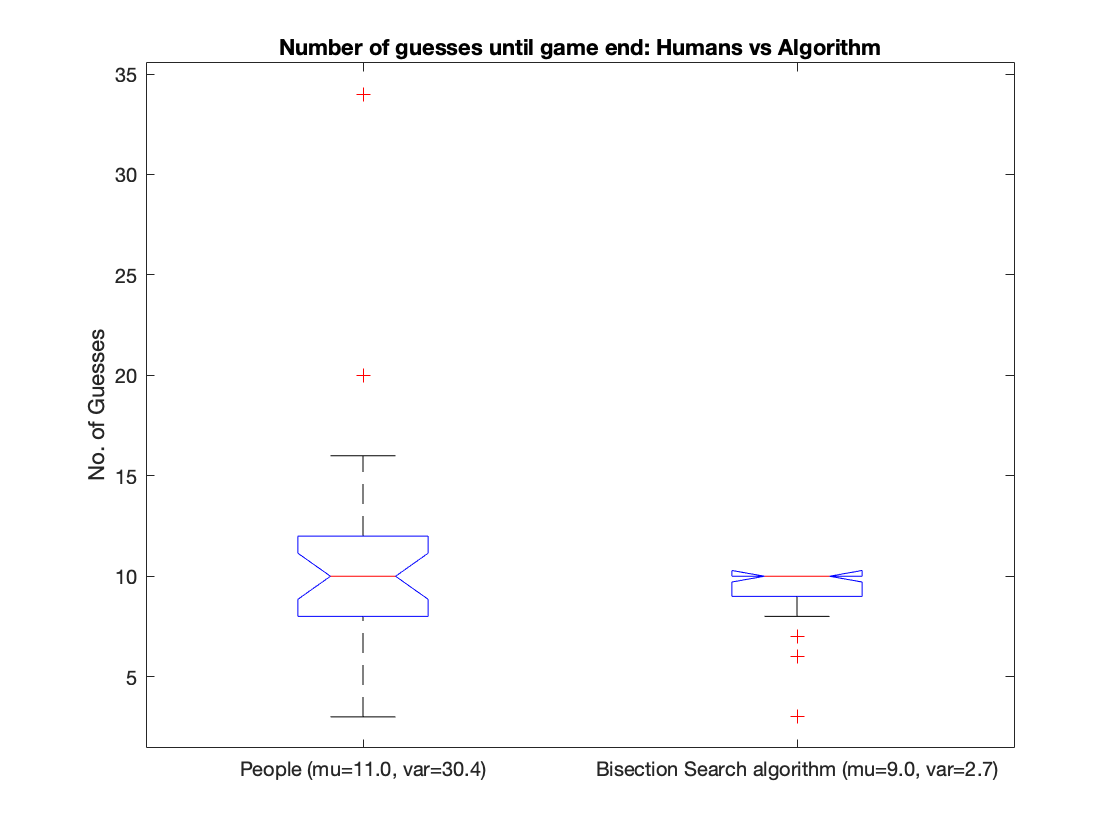


machine_nTurns = [10, 10, 9, 10, 3, 9, 9, 10, 10, 8, 10, 9, 9, 10, 10, ...
    8, 9, 10, 10, 10, 10, 7, 10, 10, 10, 10, 6, 8, 9, 6]'; 
% Bisection Search has worst-case complexity of O(logN). note that 10 ~= log(1000)

figure
boxplot([people_nTurns, machine_nTurns],'Notch','on','Labels', ...
    {'People (mu=11.0, var=30.4)', 'Bisection Search algorithm (mu=9.0, var=2.7)'})
ylabel('No. of Guesses')
title("Number of guesses until game end: Humans vs Algorithm")
hold off


% compare people who knew bisection search to those who did not
[mean(people_nTurns(class)), var(people_nTurns(class))]

ans =    10.3333   10.9524


[mean(people_nTurns(~class)),  var(people_nTurns(~class))]

ans =    11.7333   50.9238


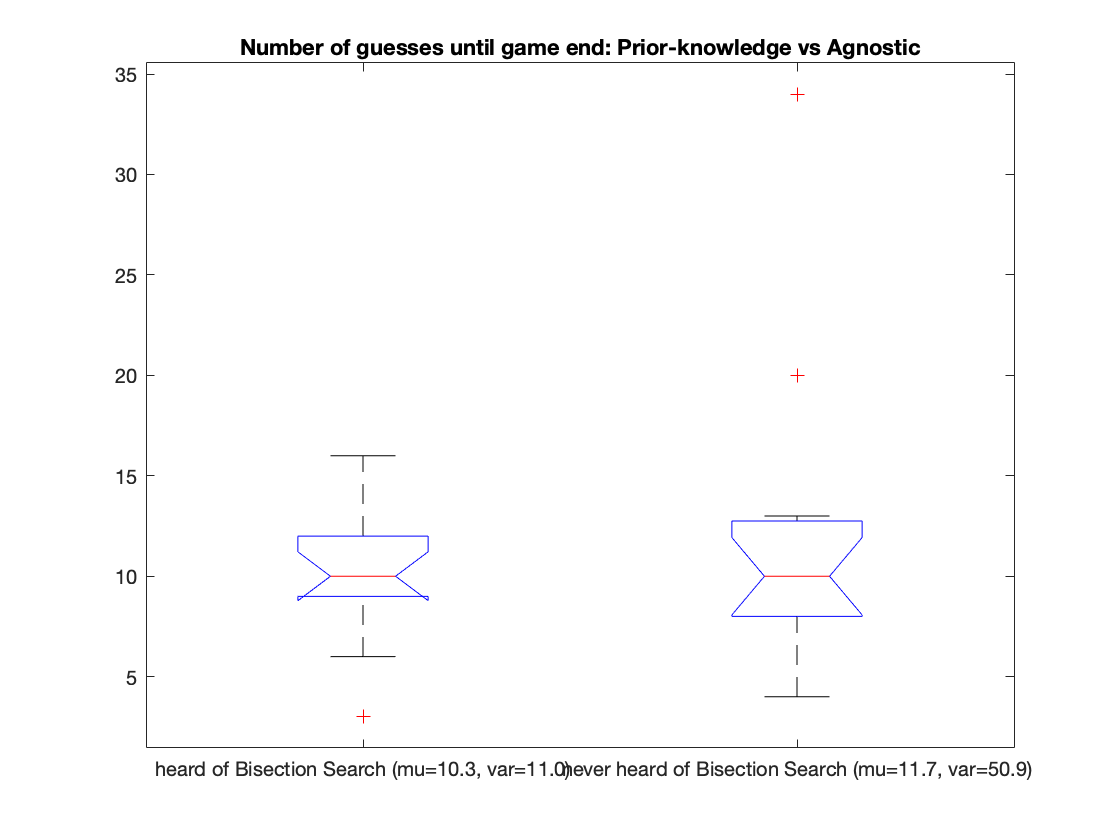


figure
boxplot([people_nTurns(class), people_nTurns(~class)],'Notch','on','Labels', ...
    {'heard of Bisection Search', 'never heard of Bisection Search'})
title("Number of guesses until game end: Prior-knowledge vs Agnostic")
hold off